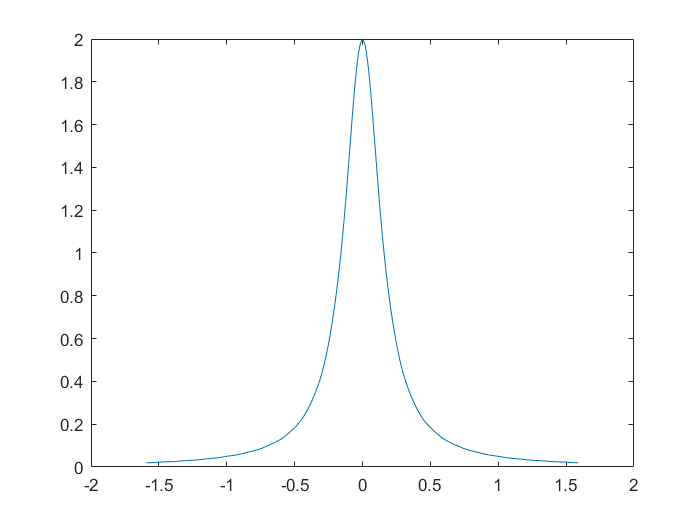

clc
clear
close all

Fs=100;
delt=1/Fs;
tvec=-2*pi:delt:2*pi;
x_t=zeros(size(tvec));
x_t(tvec>=-2*pi & tvec<=2*pi)=exp(-abs(tvec( tvec>=-2*pi & tvec<=2*pi)));
delw=0.01*pi;
%Fourier series
omegavec=-2*pi*Fs/2:delw:2*pi*Fs/2;
omegavec=-10:delw:10;
for kx=1:length(omegavec)
    w=omegavec(kx);
    basis1=exp(-1i*w*tvec);
    xw(kx)=trapz(tvec,x_t.*basis1);
end
figure(1);
plot(omegavec/(2*pi),abs(xw));

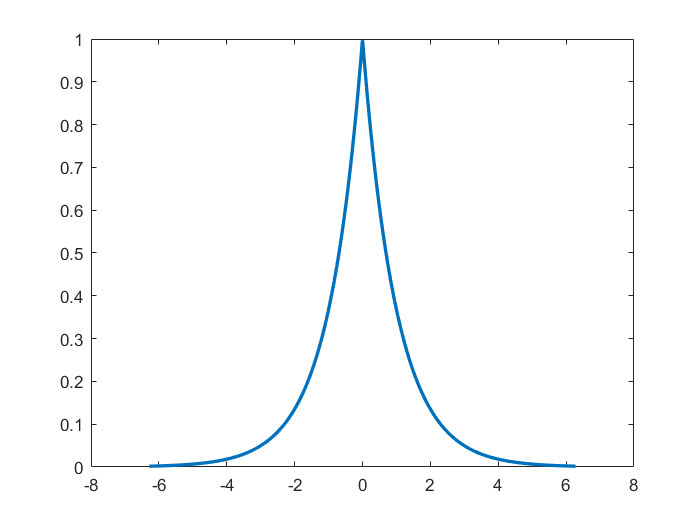

for tx=1:length(tvec)
    t=tvec(tx);
    basis2=exp(-1i*t*omegavec);
    xtrec(tx)=(1/(2*pi))*trapz(omegavec,xw.*basis2);
end
figure(2);
plot(tvec,x_t,'Linewidth',2);

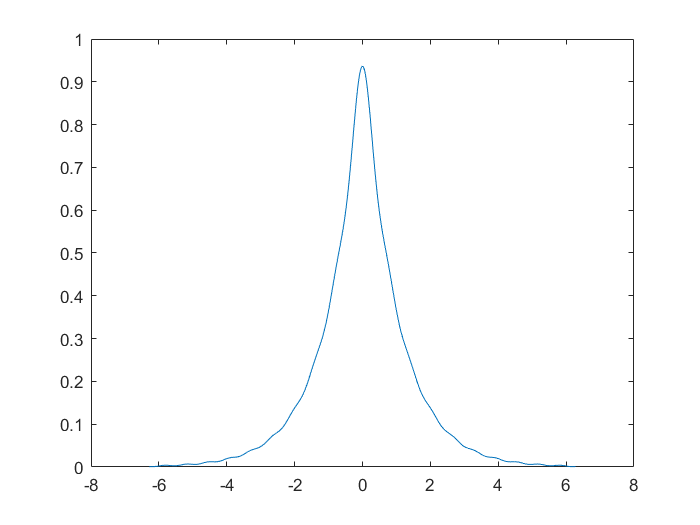

plot(tvec,xtrec);